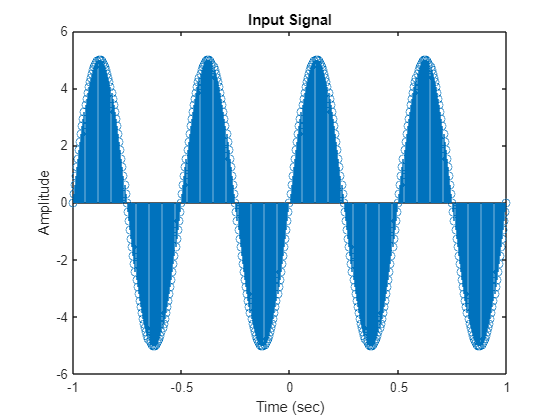

% Define sampling frequency and time increment
fs = 200;
dt = 1/fs;

% Define time vector
t = -fs/2:dt:fs/2-dt;

%subplot(5,1,1)
% Generate sinusoidal signal and ploting
x = 5*sin(2*pi*2*t);
stem(t, x);
xlim([-1 1]);
ylim([-6 6]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Input Signal');

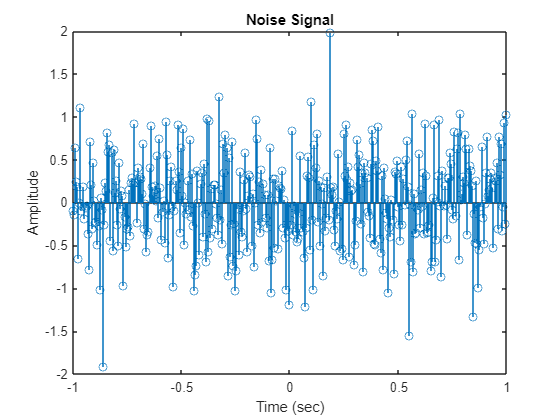


%subplot(5,1,2)
% Add uniform noise
noise = 0.5*randn(size(t));
stem(t, noise);
xlim([-1 1]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Noise Signal');

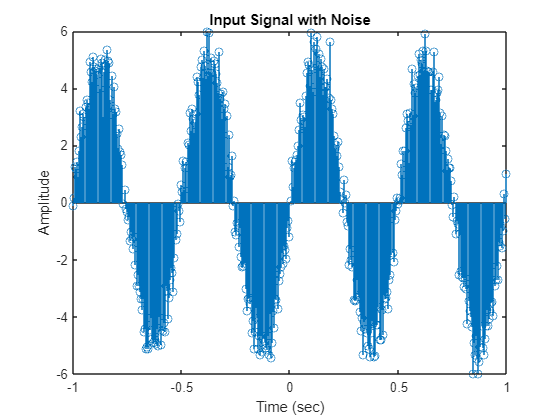


%subplot(5,1,3)
x_noise = x + noise;
% Plot signal against time
stem(t, x_noise);
xlim([-1 1]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Input Signal with Noise');



%subplot(5,1,4)
% Compute FFT and shift it
X = fftshift(fft(x_noise));
stem(t, X);

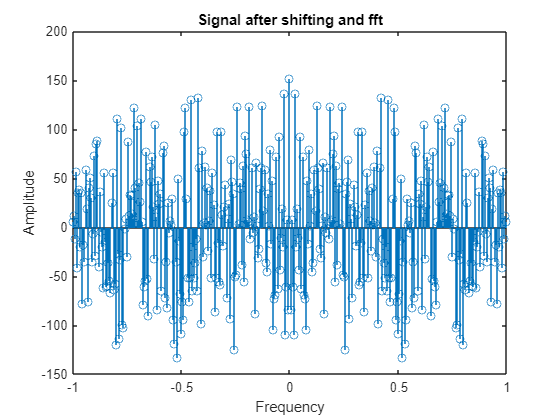

xlim([-1 1]);
xlabel('Frequency');
ylabel('Amplitude');
title('Signal after shifting and fft');

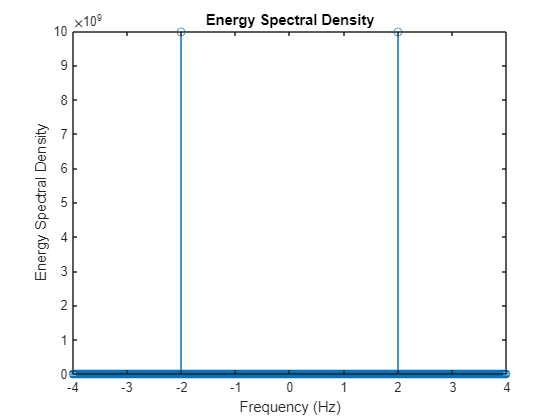



% Compute magnitude spectrum
X = abs(X);

% Compute energy spectral density
X = X.^2;

% Compute total energy
total_energy = sum(X)*dt*fs/length(x);

% Compute frequency vector
f = (-length(x)/2:1:length(x)/2-1)*fs/length(x);

% Plot energy spectral density against frequency
%subplot(5,1,5)
stem(f, X);
xlim([-4 4]);
xlabel('Frequency (Hz)');
ylabel('Energy Spectral Density');
title('Energy Spectral Density');


% Find frequencies at which most of the energy is concentrated
[max_energy, max_index] = max(X);
freqs_of_interest = f(max_index-5:max_index+5);

disp(['Frequencies at which most of the energy is concentrated: ', num2str(freqs_of_interest)]);

Frequencies at which most of the energy is concentrated: -2.025       -2.02      -2.015       -2.01      -2.005          -2      -1.995       -1.99      -1.985       -1.98      -1.975
